we declare the parameters defining the geometry of the domain

D = 0.10;              %diameter of pipe in meters
Wb = 0.75;             %bulk velocity at inlet in m/s
rho = 998.23;          %density in kg/m^3
ni = 1e-6;             %kynematic viscosity in m^2/s
mu = rho * ni;         %dynamic viscosity in Pa * s
Re = Wb * D / ni 

Re = 7.5000e+04

% %import the simulation data to be processed
% data_simulation('C:\Users\marta\OneDrive - Politecnico di Milano\AAAUNI\MAGISTRALE\PRIMO ANNO\FLUID LABS\Lab_tests\CFD2\simulations\base\phi', 'C:\Users\marta\OneDrive - Politecnico di Milano\AAAUNI\MAGISTRALE\PRIMO ANNO\FLUID LABS\Lab_tests\CFD2\simulations\base\phi.mat')

%load('C:\Users\marta\OneDrive - Politecnico di Milano\AAAUNI\MAGISTRALE\PRIMO ANNO\FLUID LABS\Lab_tests\CFD2\simulations\base\phi.mat')

'data_simulation' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\sanni\OneDrive\Desktop\POLIMI\quarto anno\fluids labs\LABS FINAL\lab2\CFD2\CFD2\matlab\codes

Change the MATLAB current folder or add its folder to the MATLAB path.

Now we want to plot the variation along z of the z-velocity, to see where it starts to be negligible, that is where the flow can be considered fully developed. Note that DWDZ is stored in the centre of the cells in Phoenics, while W1 is stored in the 'H'  faces.

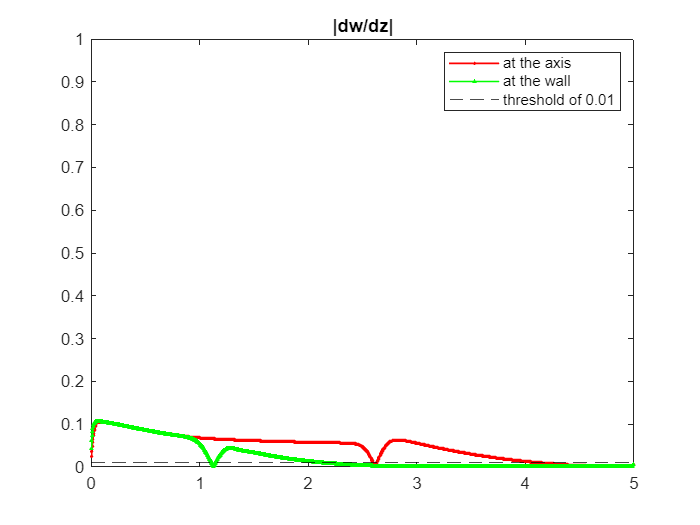

Z_C = squeeze(Z_C);
DWDZ = squeeze(DWDZ);

figure()
plot(Z_C, abs(DWDZ(1, :)), 'r-o', 'LineWidth', 1, 'MarkerSize', 1);
hold on;
plot(Z_C, abs(DWDZ(10, :)), 'g-^', 'LineWidth', 1, 'MarkerSize', 1);
yline(0.01, 'k--')
title('|dw/dz|')
legend('at the axis', 'at the wall', 'threshold of 0.01')
ylim([0, 1])
hold off;
W1 = squeeze(W1);
Z_H = squeeze(Z_H);
diff = (W1(:, 2:end) - W1(:, 1:end-1))./(Z_H(2:end)-Z_H(1:end-1));

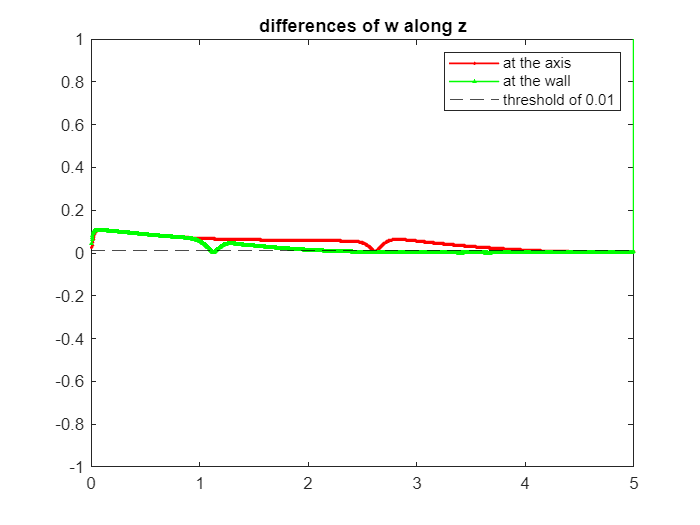

figure()
plot(Z_H(2:end), abs(diff(1, :)), 'r-o', 'LineWidth', 1, 'MarkerSize', 1);
hold on;
plot(Z_H(2:end), abs(diff(10, :)), 'g-^', 'LineWidth', 1, 'MarkerSize', 1);
yline(0.01, 'k--')
title('differences of w along z')
legend('at the axis', 'at the wall', 'threshold of 0.01')
ylim([-1, 1])
hold off;
%Now we obtain the first value such that the derivative is under the
%threshold
threshold = 0.01;

counter=1;
while (max(abs(DWDZ(:, counter))) > threshold) || (Z_C(counter)<=3)
under_th = abs(DWDZ(:, counter));
counter=counter+1;
end

counter

Now to check for the physical soundness of the solution, we plot the pression and velocity profiles along some segments

Z_C = squeeze(Z_C);

counter = 1236

P1 = squeeze(P1);
figure()
subplot(2, 1, 1)
plot(Z_C, P1(1, :), 'r-o', 'LineWidth', 1, 'MarkerSize', 1)
hold on;
plot(Z_C, (P1(1, end)-P1(1, 1))/(Z_C(end)-Z_C(1)).*Z_C  + P1(1, 1), 'k--') %retta tra punto iniziale e punto finale
m = (P1(1, end)-P1(1, counter))/(Z_C(end)-Z_C(counter)); %only in the fully developed region
intercept = P1(1, end) - m*Z_C(end);
plot(Z_C(counter:end), m*Z_C(counter:end) + intercept, 'g-^', 'MarkerSize', 1)
title("Pression at the axis")
legend("Pression", "Line between extremals", 'Line in f.d.region')
hold off

subplot(2, 1, 2)
plot(Z_C, P1(10, :), 'r-o', 'LineWidth', 1, 'MarkerSize', 1)
hold on;
plot(Z_C, (P1(10, end)-P1(10, 1))/(Z_C(end)-Z_C(1)).*Z_C  + P1(10, 1), 'k--')
m = (P1(10, end)-P1(10, counter))/(Z_C(end)-Z_C(counter));
intercept = P1(10, end) - m*Z_C(end);
plot(Z_C(counter:end), m*Z_C(counter:end) + intercept, 'g-^', 'MarkerSize', 1)
title("Pression at the wall")
legend("Pression", "Line between extremals", 'Line in f.d.region')
hold off

Now we plot W/Wb versus r/R.

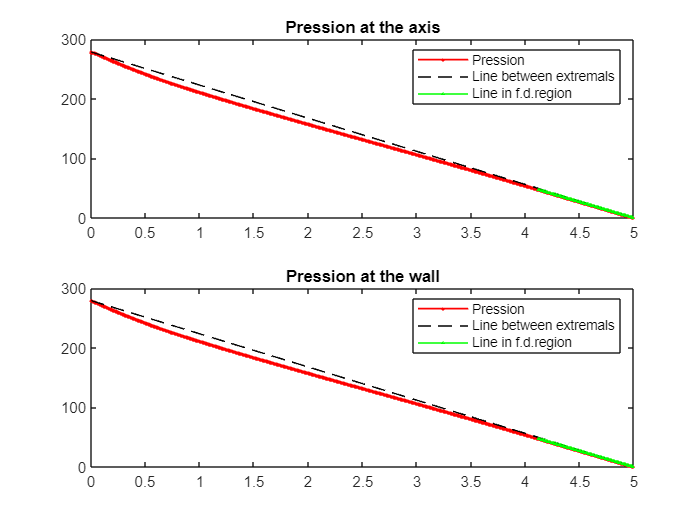

R=0.10/2; %pipe radius
Wb = 0.75;             %bulk velocity at inlet in m/s
Y_C = squeeze(Y_C);

W1 = squeeze(W1);
W0=W1(1, fix(0.90*counter));

figure()
plot(Y_C./R, W1(:, 2)./Wb, 'b--', 'LineWidth', 1, 'MarkerSize', 4)
hold on;
plot(Y_C./R, W1(:, ceil(0.25*end))./Wb, 'c-+', 'LineWidth', 1, 'MarkerSize', 4)
plot(Y_C./R, W1(:, ceil(0.50*end))./Wb, 'm-x', 'LineWidth', 1, 'MarkerSize', 4)
plot(Y_C./R, W1(:, ceil(0.90*end))./Wb, 'k-.', 'LineWidth', 1, 'MarkerSize', 4)
plot(Y_C./R, W1(:, ceil(0.95*end))./Wb, 'r-o', 'LineWidth', 1, 'MarkerSize', 4)
plot(Y_C./R, W1(:, end-1)./Wb, 'g-^', 'LineWidth', 1, 'MarkerSize', 4)
%Power law profile of Nikuradse, checked at 0.90*counter
plot(Y_C./R, ((1-Y_C./R).^(1/7)).*W0, 'k', 'LineWidth', 2, 'MarkerSize', 4); 
title("W/Wb versus r/R")
legend("W at inlet+1", "W at 25% of length", "W at 50% of length", "W at 90% of length", "W at 95% of length", "W at end of pipe", "Power law profile of Nikuradse", 'Location', 'southwest')
hold off

Now we study w^+ versus y^+

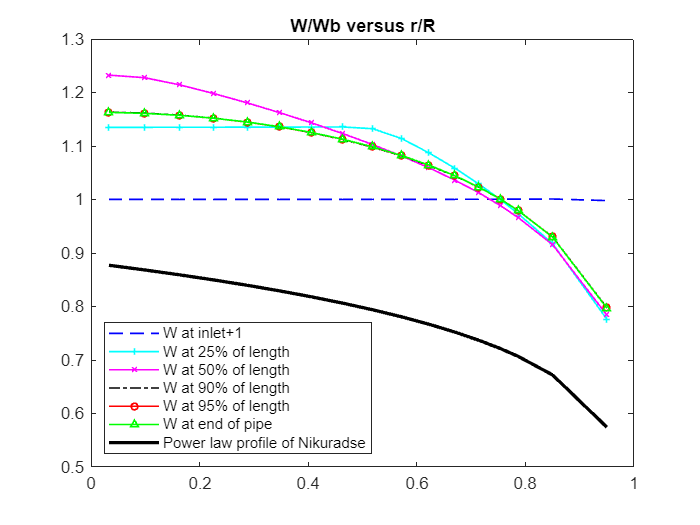

tau_wall= STRS(end, counter)*rho; %shear stress at the wall in fully developed flow
delta_ni= ni/(sqrt(tau_wall/rho)); %viscous length scale
YPLS=squeeze(YPLS);


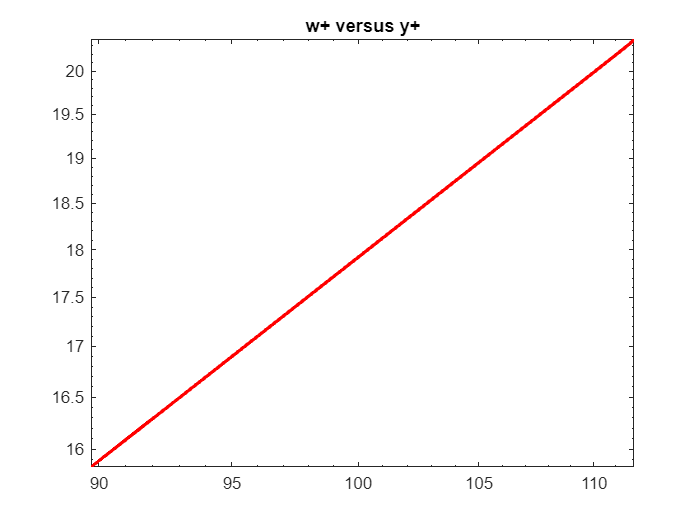

w_tau=sqrt(tau_wall/rho); %friction velocity
W_plus=W1./w_tau; 

g=@(x) ((1/0.41).*log(x) + 5); %log law of inner layer

figure();
loglog(YPLS(end, :), W_plus(end, :), 'r-', 'LineWidth',2, 'MarkerSize',4);
title('w+ versus y+')
figure(); 
loglog(YPLS(end, :), g(YPLS(end, :)), 'b--', 'LineWidth',2, 'MarkerSize',4);
hold on;
loglog(YPLS(end, :), W_plus(end, :), 'r-', 'LineWidth',2, 'MarkerSize',4);
legend('loglaw layer', 'w+ versus y+');


legend('Location', 'northwest')

now we check the behaviour of the shear stress tau(r) / tau_wall, in partitcular we check tau viscous and tau raynolds behaviour

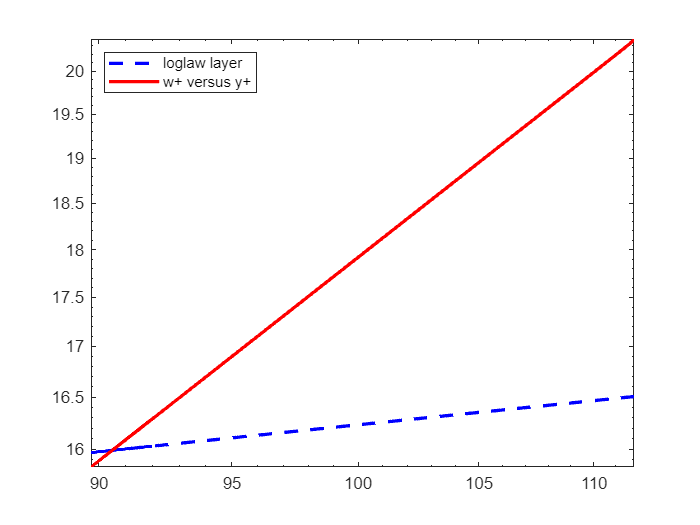

R=0.05;
DWDY=squeeze(DWDY); 
KE=squeeze(KE); %k
EP=squeeze(EP); %epsilon
STRS=squeeze(STRS); %stress
rho = 998.23;          %density in kg/m^3

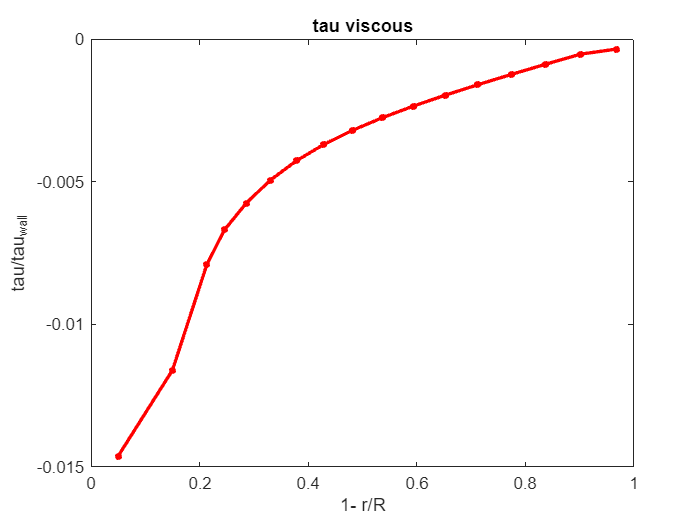

Y_C=squeeze(Y_C);
tau_wall= STRS(end, counter)*rho; %shear stress at the wall in fully developed flow

ni = 1e-6;             %kynematic viscosity in m^2/s
mu = rho * ni;         %dynamic viscosity in Pa * s
tau_viscous=mu.*DWDY(:, counter);
C_mu = 0.09;
mu_t = rho .* C_mu .* (((KE(:, counter)).^2) ./ EP(:, counter));
tau_reynolds = mu_t .*(DWDY(:, counter));
figure();
plot((1-Y_C./R), (tau_viscous')./tau_wall, 'r*-', 'LineWidth',2, 'MarkerSize',4);
title('tau viscous');
xlabel('1- r/R')
ylabel('tau/tau_{wall}')

figure()
plot((1-Y_C./R), (tau_reynolds')./tau_wall, 'b*-','LineWidth',2, 'MarkerSize',4);
hold on
plot((1-Y_C./R), (-(tau_viscous')+tau_wall*(1-Y_C./R))./tau_wall, 'g*-','LineWidth',2, 'MarkerSize',4);
xlabel('1- r/R')
ylabel('tau/tau_{wall}')

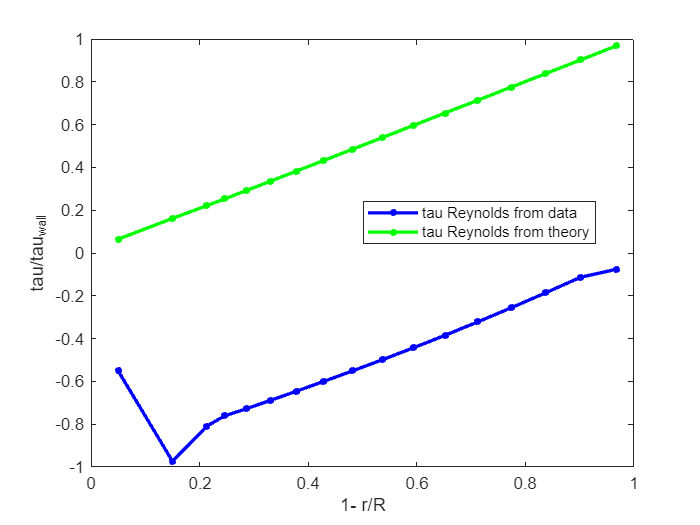

legend('tau Reynolds from data', 'tau Reynolds from theory')
legend("Position", [0.51881,0.53437,0.33214,0.082143])
figure()
plot((1-Y_C./R), ((tau_reynolds+tau_viscous)./tau_wall), 'g*-','LineWidth',2, 'MarkerSize',4);
hold on
plot((1-Y_C./R), (1-Y_C./R), 'k--', 'LineWidth',2, 'MarkerSize',4);
legend('empirical total shear stress', 'theoretical total shear stress');
legend("Position", [0.4884,0.53151,0.36071,0.082143])
xlabel('1 - r/R')

ylabel('tau/tau_{wall}')

Now we start the validation, making a comparison with Torbergsen data and other literature 

run('import_Torbergsen_data_from_Excel.m')

Axial Reynolds-averaged velocity validation with Torbergsen 

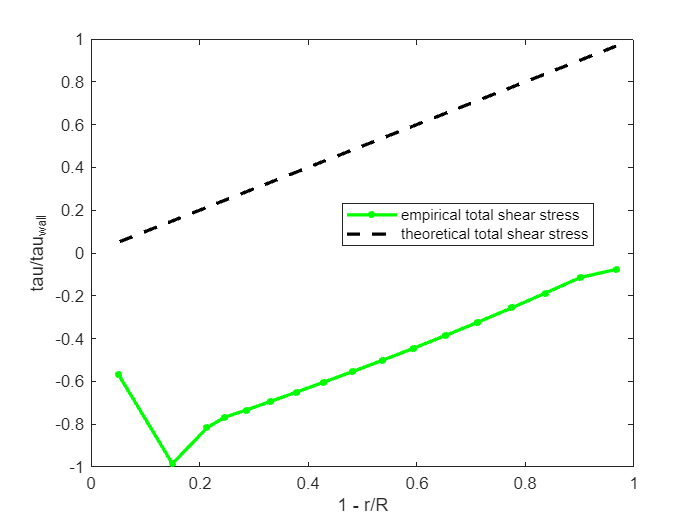

R=0.10/2; %pipe radius
Wb = 0.75; %bulk velocity at inlet in m/s
Y_C = squeeze(Y_C); %r
W1 = squeeze(W1); %axial velocity obtained by PHEONICS
%we study at fully developed flow


figure()
subplot(2, 1, 1)%% SERIES 1
plot(Y_C./R, W1(:, counter)./Wb, 'r*--', 'LineWidth', 1, 'MarkerSize', 4)
hold on;
plot(W_profile_series1(:, 1), W_profile_series1(:, 2), 'b+-', 'LineWidth',2, 'MarkerSize',4);
legend('Simulation data', 'Torbergsen data');
title("W/W_b versus r/R");
legend("Position", [0.14517,0.65722,0.24643,0.082143])
subplot(2, 1, 2)%% SERIES 2
plot(Y_C./R, W1(:, counter)./Wb, 'r*--', 'LineWidth', 1, 'MarkerSize', 4)
hold on;
plot(W_profile_series2(:, 1), W_profile_series2(:, 2), 'b+-', 'LineWidth',2, 'MarkerSize',4);
legend('Simulation data', 'Torbergsen data');
title("W/W_b versus r/R");
legend("Position", [0.14517,0.65722,0.24643,0.082143])

Now we validate our model using the power law profile of Nikuradse

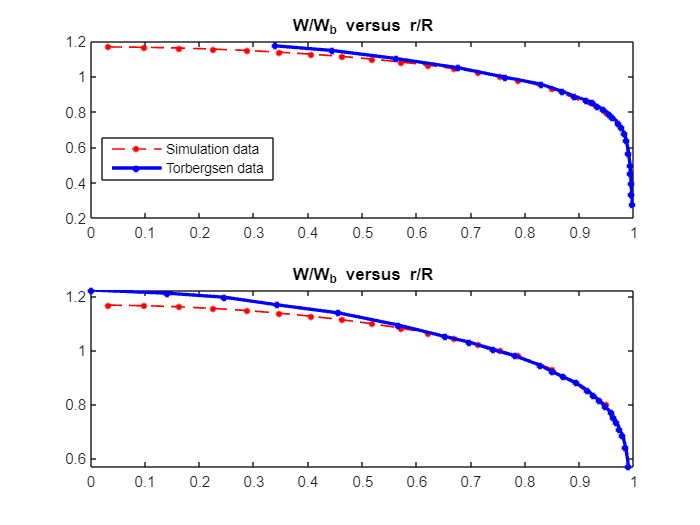

% CASE 1 : f_CFD= moody diagram >> 0.03
f_CFD1=0.03;
n=f_CFD1^(-0.5);
W_norm_1= (((2*n+1)*(n+1))./(2*n.^2))*((1-Y_C./R).^(1/n)); %W/W_bulk calculated accordingly to power law profile of Nikuradse

%CASE 2: f_CFD as solution of Prandtl’s formula
f = @(x) 1./sqrt(x) + 2*log10(2.51./(Re*sqrt(x)));
df = @(x) -0.5*x.^(-3/2) - (1./(x*log(10)));
[f_CFD2, newton_success]=newton(f, df, 0.02, 1e-8, 2000);
n=f_CFD2^(-0.5);
W_norm_2= (((2*n+1)*(n+1))./(2*n.^2))*((1-Y_C./R).^(1/n));


%CASE 3: f_CFD as solution of Haaland formula
f_CFD3= (1/(-1.8*log10(6.9/Re))).^2;
n=f_CFD3^(-0.5);
W_norm_3= (((2*n+1)*(n+1))./(2*n.^2))*((1-Y_C./R).^(1/n));
figure()
subplot(3, 1, 1);
plot(Y_C./R, W1(:, counter)./Wb, 'r*--', 'LineWidth', 1, 'MarkerSize', 4)
hold on; 
plot(Y_C./R, W_norm_1,'b+-', 'LineWidth',2, 'MarkerSize',4 );
legend('data', 'f^{CFD} from Moody diagram')
title('Simulation Reynolds-Averaged axial velocity versus power law profile of Nikuradse')

subplot(3, 1, 2);
plot(Y_C./R, W1(:, counter)./Wb, 'r*--', 'LineWidth', 1, 'MarkerSize', 4);
hold on; 
plot(Y_C./R, W_norm_2,'g+-', 'LineWidth',2, 'MarkerSize',4 );
legend('data', 'f^{CFD} from Prandtl')

subplot(3, 1, 3)
plot(Y_C./R, W1(:, counter)./Wb, 'r*--', 'LineWidth', 1, 'MarkerSize', 4);
hold on; 
plot(Y_C./R, W_norm_3,'k+-', 'LineWidth',2, 'MarkerSize',4 );
legend('data', 'f^{CFD} from Haaland')

subplot(3,1,1)
legend("Position", [0.16711,0.74944,0.30714,0.077381])
subplot(3,1,2)
legend("Position", [0.16524,0.44658,0.23571,0.077381])
subplot(3,1,3)
legend("Position", [0.16024,0.15135,0.24643,0.077381])

Now we validate w+ versus y+ , using Lauder and Spaulding function

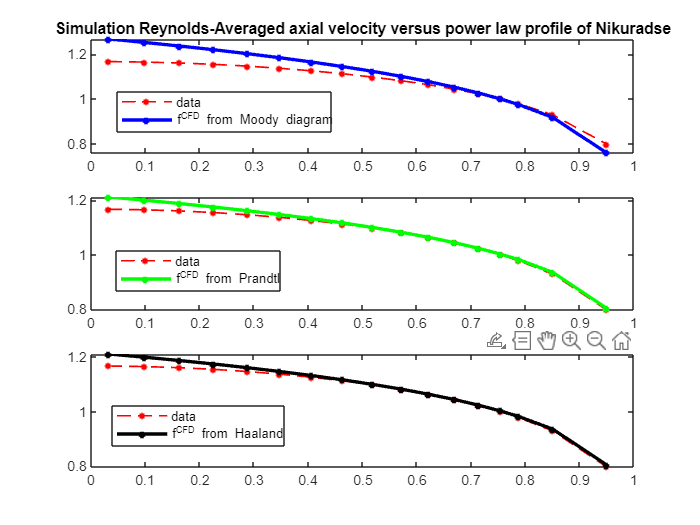

tau_wall= STRS(end, counter)*rho; %shear stress at the wall in fully developed flow
YPLS=squeeze(YPLS); %numerical y+

w_tau=sqrt(tau_wall/rho); %friction velocity
WPLS=W1./w_tau; %numerical u+
g=@(x) (1/0.41)*log(8.6*x); %wall function in our y+ range
delta_ni= ni/(w_tau); %viscous length scale
Y_plus=(R-Y_C)./delta_ni;


figure();
loglog(Y_plus, WPLS(:, counter), 'r-', 'LineWidth',2, 'MarkerSize',4);

hold on
loglog(Y_plus, g(Y_plus), 'b-', 'LineWidth', 2, 'MarkerSize',4);
xlabel('y+'); ylabel('w+'); title('Wall function validation');
legend('Simulation w+ versus y+', 'Wall function pattern');
legend("Position", [0.17595,0.79722,0.325,0.082143])

Kinetic energy along pipe radius validation: Torgbersen data and Kam Hong Ng function

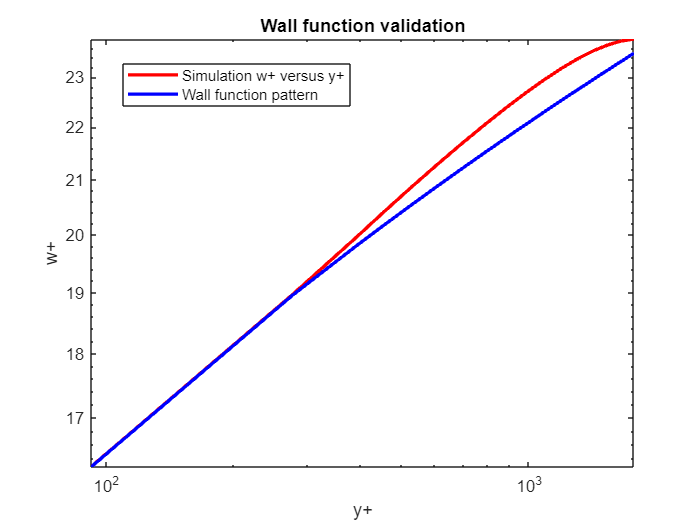


figure()
subplot(2, 1, 1)
plot(Y_C./R, KE(:, counter)./(Wb.^2), 'r*-', 'LineWidth',2, 'MarkerSize',4  );
hold on; 
plot(k_profile(:, 1), k_profile(:, 2), 'b+-', 'LineWidth',2, 'MarkerSize',4);
title('Comparison with Torgbergsen data'); legend('Simulation data', 'Torgbergsen data'); xlabel('r/R'); ylabel('K/Wb^2');


f=@(x, F) (F/8).*(1+ (2/3).*x + (10/3).*x.^3 ); %Kam Hong Ng function

subplot(2, 1, 2)
plot(Y_C./R, KE(:, counter)./(Wb.^2), 'r*-', 'LineWidth',2, 'MarkerSize',4  );
hold on

%moody friction factor
plot(Y_C./R, f(Y_C./R, f_CFD1), 'b-', 'LineWidth',2, 'MarkerSize',4  );
%Prandtl friction factor
plot(Y_C./R, f(Y_C./R, f_CFD2), 'k-', 'LineWidth',2, 'MarkerSize',4  );
%Haaland friction factor
plot(Y_C./R, f(Y_C./R, f_CFD3), 'g-', 'LineWidth',2, 'MarkerSize',4  );
title('Comparison with  Kam Hong Ng function'); xlabel('r/R'); ylabel('K/Wb^2'); 
legend('Simulation data', 'Moody f^{CFD}', 'Prandtl f^{CFD}', 'Haaland f^{CFD}');
subplot(2,1,2)

dissipation rate validation $\varepsilon$ with Torbergsen and relation between $\varepsilon$ and k.

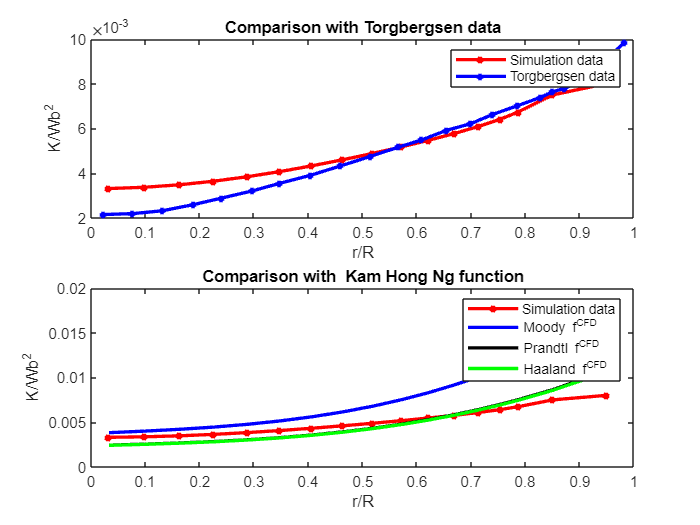

figure();
subplot(2, 1, 1)
plot(Y_C./R, EP(:, counter)*R/(Wb^3), 'r*-', 'LineWidth',2, 'MarkerSize',4 );
hold on;
%Torgbergsen 
plot(eps_profile_series1(:, 1), eps_profile_series1(:, 2), 'b-', 'LineWidth',2, 'MarkerSize',4);
plot(eps_profile_series2(:, 1), eps_profile_series2(:, 2), 'g-', 'LineWidth',2, 'MarkerSize',4);
plot(eps_profile_series3(:, 1), eps_profile_series3(:, 2), 'k-', 'LineWidth',2, 'MarkerSize',4);
ylabel('eps*R/Wb^3'); xlabel('r/R'); title('Comparison with Torbergsen data');
legend('Simulation data', 'Torbergsen data 1', 'Torbergsen data 2', 'Torbergsen data 3');
legend("Position", [0.2381,0.72722,0.26429,0.15595])

Cd=0.1643;
f=@(x, F) (F/8).*(1+ (2/3).*x + (10/3).*x.^3 ); %Kam Hong Ng function, F friction factor

lm=@(r) R*(0.14 -0.08*r.^2 -0.06*r.^4 ); %mixing length
e=@(r, F) Cd*(f(r, F).^(3/2))./(lm(r)); % k-eps relation

subplot(2, 1, 2);
plot(Y_C./R, EP(:, counter)*R/(Wb^3), 'r*-', 'LineWidth',2, 'MarkerSize',4 );
hold on;
%moody friction factor
plot(Y_C./R, e(Y_C./R, f_CFD1), 'b-', 'LineWidth',2, 'MarkerSize',4  );
%Prandtl friction factor
plot(Y_C./R, e(Y_C./R, f_CFD2), 'k-', 'LineWidth',2, 'MarkerSize',4  );
%Haaland friction factor
plot(Y_C./R, e(Y_C./R, f_CFD3)*R/(Wb^3), 'g-', 'LineWidth',2, 'MarkerSize',4  );
ylabel('eps*R/Wb^3'); xlabel('r/R'); title('Comparison with theoretical k-eps relation');
legend('Simulation data', 'f^{CFD} Moody', 'f^{CFD} Prandtl', 'f^{CFD} Haaland');
subplot(2,1,2)
legend("Position", [0.23738,0.26001,0.225,0.15833])